clear;
currentDir = pwd;
idx = strfind(currentDir, 'chicago_crime');
if isempty(idx)
    error('Run this inside the chicago_crime folder');
end
rootFolder = currentDir(1:idx + length('chicago_crime') - 1);
addpath(genpath(fullfile(rootFolder, '..')));
dataPath = fullfile(rootFolder, ...
    'tensor_data_chicago_crime-master', ...
    'chicago_crime_2019.mat');
if ~isfile(dataPath)
    error('File not found: %s', dataPath);
end
data = load(dataPath);

F = data.X; 
A = double(full(sptensor(F.subs,F.vals,F.size)));

% HT approximation of tensor
opts.max_rank = 25;
opts.rel_eps = 1e-4;
A_ht = truncate(A,opts); 
A_htFull = full(A_ht);
norm(A_htFull - A, 'fro')/norm(A,'fro')

ans = 0.9032

Compute $\mathcal{X}_r$ for ranks $r = 1$ to $20$.

Runtime is around an hour. 

% ranks = 1:20; 
% % relErr = zeros(numel(ranks),1); 
% % tic
% % normA = norm(A,'fro'); 
% % for k = 1:numel(ranks)
% %     r = ranks(k)*ones(1,2*ndims(A_ht)-1); 
% %     X = nhtd_mu(A_ht,'rank',r,'max_it',5000,'print',false); 
% %     relErr(k) = norm(A - full(X), 'fro')/normA; 
% %     toc
% % end 
% % toc
% % 
% figure;
% plot(ranks, relErr, 'k:', 'LineWidth',1.0)
% hold on
% plot(ranks,relErr,'bx','MarkerSize',12)
% hold off
% xlabel('Rank'); ylabel('Relative Error'); 
% exportgraphics(gcf, 'rel_error.pdf', 'ContentType', 'vector')

%Compute NHTD X of A
selected_rank = 7;
r = selected_rank*ones(1,2*ndims(A_ht)-1); 
X = nhtd_mu(A_ht,'rank',r,'print',false); 

Contributions of features of $U_1, U_2, U_3, U_4$

G = core_ten(X); 
cns = contributions(G); 
sorted = cell(ndims(X),1); 
idx_sorted = cell(ndims(X),1); 
for i = 1:ndims(X)
    [sorted{i},idx_sorted{i}] = sort(cns{i},'descend');
end  
G = G(idx_sorted{1},idx_sorted{2},idx_sorted{3},idx_sorted{4}); 

for i = 1:ndims(X)
    round(sorted{i},2)
end

ans =     0.2000
    0.1500
    0.1400
    0.1400
    0.1300
    0.1300
    0.1100


ans =     0.2500
    0.2300
    0.1700
    0.1400
    0.1300
    0.0700
    0.0200


ans =     0.5800
    0.2200
    0.0700
    0.0500
    0.0300
    0.0300
    0.0200


ans =     0.6700
    0.1500
    0.1000
    0.0400
    0.0200
    0.0100
    0.0100


Joint rate indices between lower level features

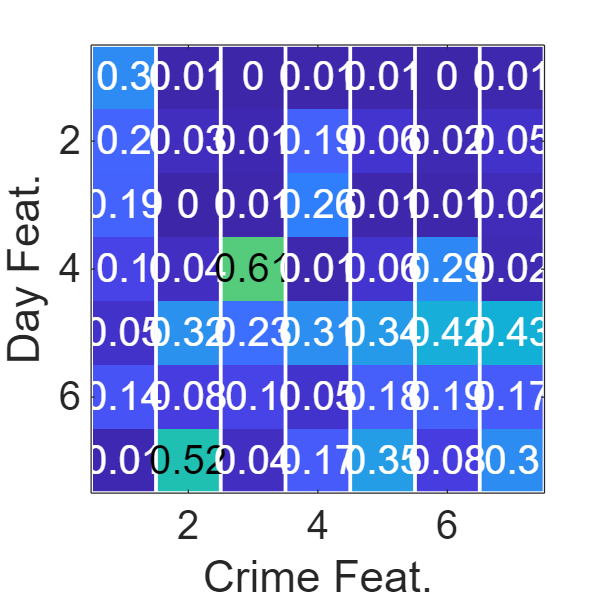

plot_mat(jr_idx(G,[1,4]),'FontSize',16)
xlabel('Crime Feat.'); ylabel('Day Feat.');
clim([0,1]); 
exportgraphics(gcf, 'jr_diagramA.pdf', 'ContentType', 'vector')

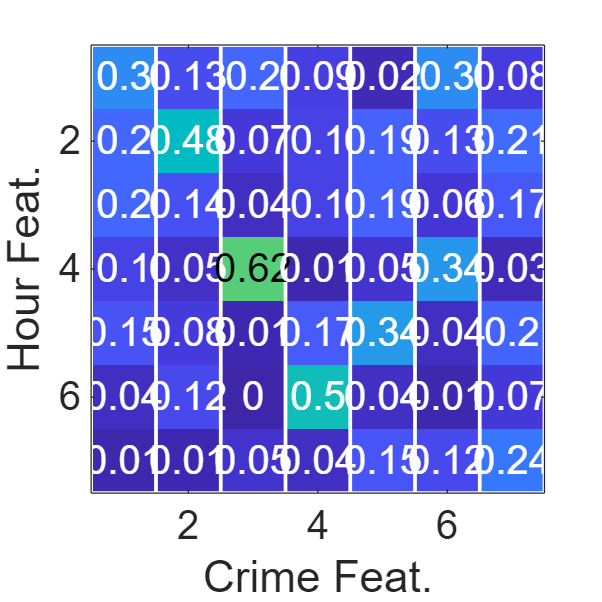


plot_mat(jr_idx(G,[2,4]),'FontSize',16)
xlabel('Crime Feat.'); ylabel('Hour Feat.');
clim([0,1]); 
exportgraphics(gcf, 'jr_diagramB.pdf', 'ContentType', 'vector')

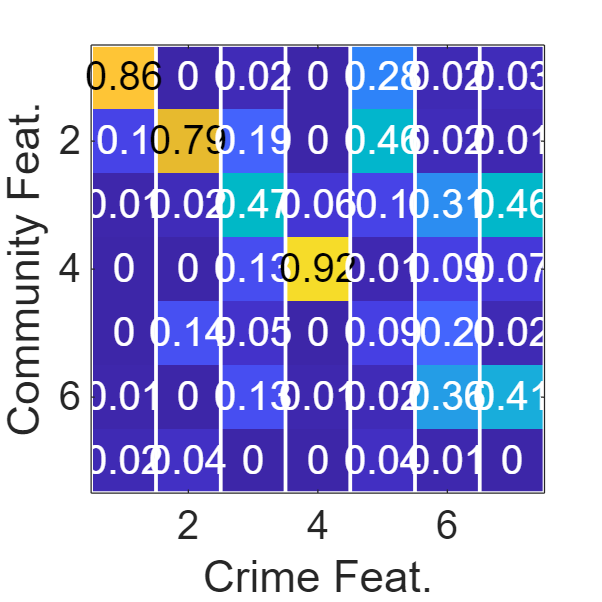


plot_mat(jr_idx(G,[3,4]),'FontSize',16)
xlabel('Crime Feat.'); ylabel('Community Feat.');
clim([0,1]); 
exportgraphics(gcf, 'jr_diagramC.pdf', 'ContentType', 'vector')

Plot frames

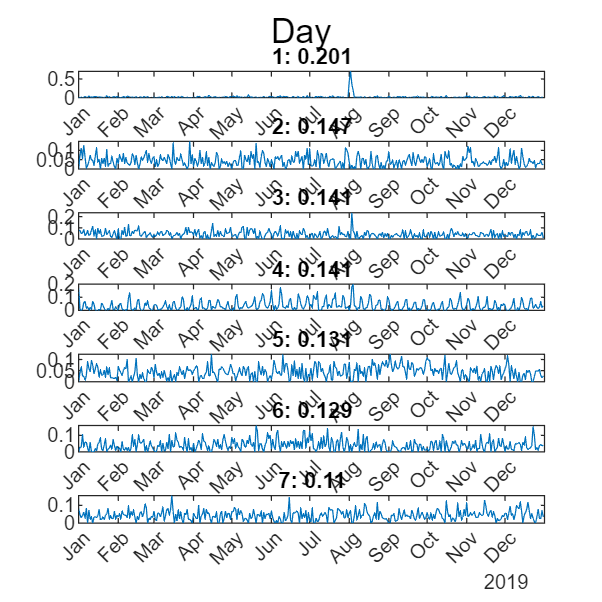

%Plot frames
U = X.U; 
%sp_sz = [4,2]; 
U1 = U{X.dim2ind(1)}; 
days = 1:365;
startDate = datetime(2019,1,1);
dates = startDate + days - 1;
plot_frames(U1(:,idx_sorted{1}),'line', ...
    'subtitles', string(1:size(U1,2))+": "+string(round(sorted{1},3))',...
    'x',dates,...
    'width',6,...
    'ratio',1,...
    'xticks',dateshift(dates(1), 'start', 'month') : calmonths(1) : dateshift(dates(end), 'start', 'month'))
xtickformat('MMM')
sgtitle('Day')
exportgraphics(gcf, 'day.pdf', 'ContentType', 'vector')

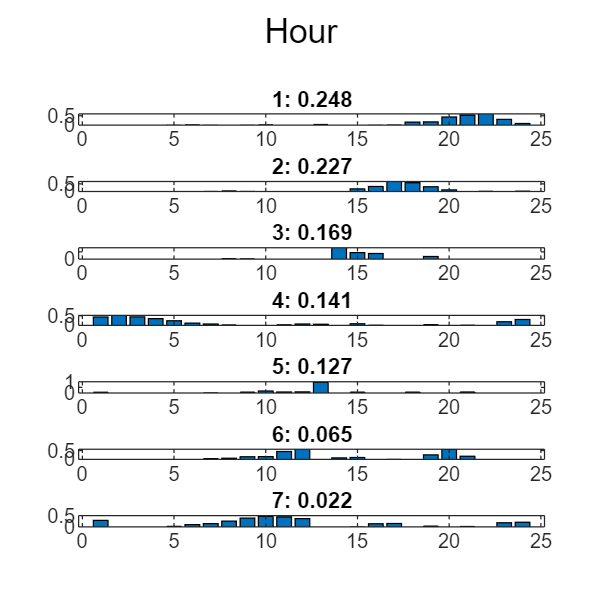


U2 = U{X.dim2ind(2)};
plot_frames(U2(:,idx_sorted{2}),'bar',...
    'subtitles', string(1:size(U2,2))+": "+string(round(sorted{2},3))',...
    'width',6, ...
    'ratio',1)
sgtitle('Hour')
exportgraphics(gcf, 'hour.pdf', 'ContentType', 'vector')

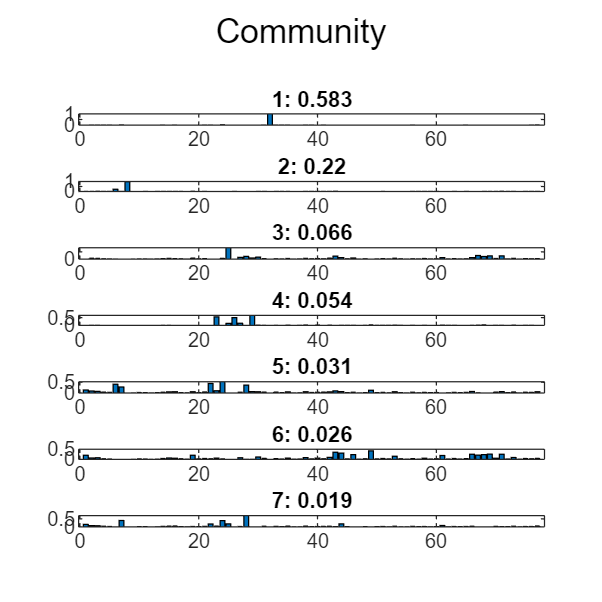


U3 = U{X.dim2ind(3)};
plot_frames(U3(:,idx_sorted{3}),'bar',...
    'subtitles', string(1:size(U3,2))+": "+string(round(sorted{3},3))',...
    'ratio', 1,...
    'width', 6)
sgtitle('Community')
exportgraphics(gcf, 'community.pdf', 'ContentType', 'vector')

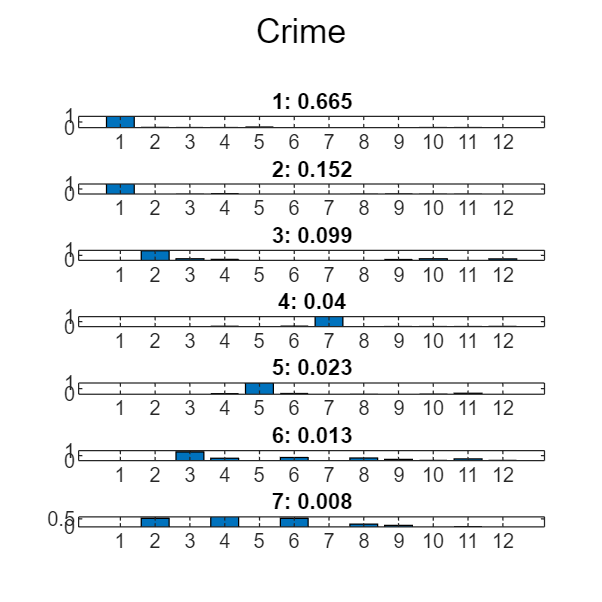


U4 = U{X.dim2ind(4)};
plot_frames(U4(:,idx_sorted{4}),'bar',...
    'subtitles', string(1:size(U4,2))+": "+string(round(sorted{4},3))',...
    'ratio', 1,...
    'width', 6)
sgtitle('Crime')
exportgraphics(gcf, 'crime.pdf', 'ContentType', 'vector')

Contributions given partition $\{\{1,2\},\{3,4\}\}$.

G_Y = X.B{1}; 
cns_Y = contributions(G_Y); 
sorted_Y = cell(ndims(G_Y),1); 
idx_sorted_Y = cell(ndims(G_Y),1); 
for i = 1:ndims(G_Y)
    [sorted_Y{i},idx_sorted_Y{i}] = sort(cns_Y{i},'descend');
end  
G_Y = G_Y(idx_sorted_Y{1},idx_sorted_Y{2});

Day-Hour Features

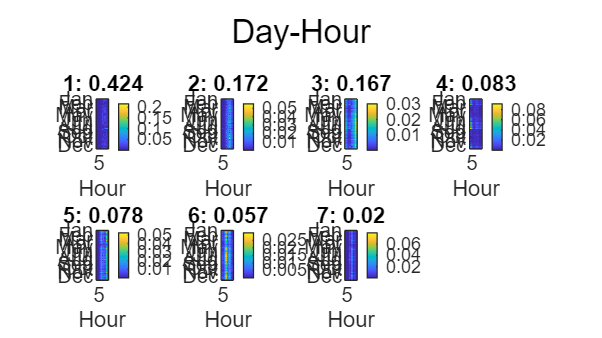

U12 = frameU(2,X); 
U12 = U12(:,idx_sorted_Y{1}); 
U12 = reshape(U12,size(X,1),size(X,2),[]);

clear days;
startDate = datetime(2019,1,1);
dates = startDate + days(0:364);
monthStarts = dateshift(dates, 'start', 'month');
[monthTicks, ~, ic] = unique(monthStarts);
monthPos = accumarray(ic, 1:length(dates), [], @min);

plot_frames(U12,'2d', ...
    'subtitles', string(1:size(U12,3))+": "+string(round(sorted_Y{1},3))',...
    'sp_sz',[2,4], ...
    'xlabel','Hour', ...
    'yticks',monthPos, ...
    'yticklabels',string(monthTicks, 'MMM'), ...
    'width',8)
sgtitle('Day-Hour'); 
exportgraphics(gcf, '12feat_imagesc.pdf', 'ContentType', 'vector')

 Line graph of Day-Hour Features

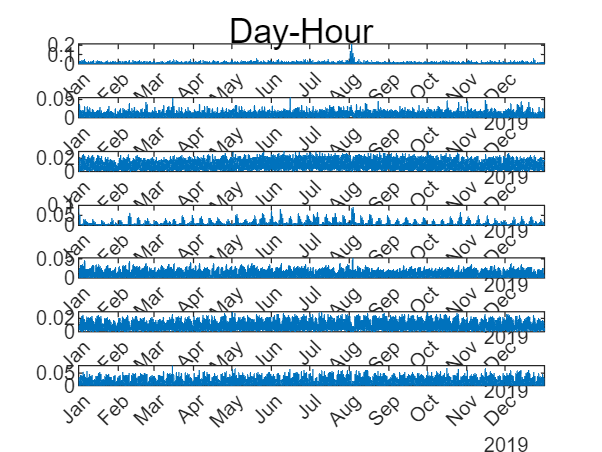

U12 = frameU(2,X); 
U12 = U12(:,idx_sorted_Y{1}); 
idx = reshape(1:size(U2,1)*size(U1,1), size(U1,1), size(U2,1))';   % swap nesting
idx = idx(:);
U12 = U12(idx, :);

t = datetime(2019,1,1,0,0,0) + hours(0:8759);   
monthTicks = dateshift(t(1), 'start', 'month') : calmonths(1) : dateshift(t(end), 'start', 'month');

plot_frames(U12,'line', ...
        'width',6,...
        'ratio',4/3,...
        'x', t, ...
        'xticks',monthTicks)
xtickformat('MMM'); 
sgtitle('Day-Hour')
exportgraphics(gcf, '12feat_plot.pdf', 'ContentType', 'vector')

Community-Crime Features

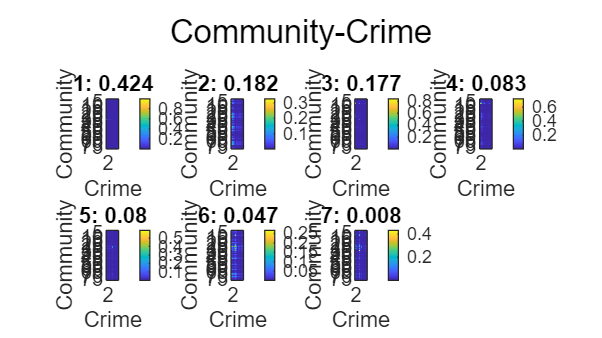

U34 = frameU(3,X);
U34 = U34(:,idx_sorted_Y{2}); 
U34 = reshape(U34,size(X,3),size(X,4),[]);
plot_frames(U34,'2d', ...
    'subtitles', string(1:size(U34,3))+": "+string(round(sorted_Y{2},3))',...
    'sp_sz',[2,4], ...
    'xlabel','Crime', ...
    'ylabel','Community',...
    'width',8,...
    'yticks',0:5:77, ...
    'YMinorTick',true)
sgtitle('Community-Crime');
exportgraphics(gcf, '34feat.pdf', 'ContentType', 'vector')

Joint rate indices between higher level features

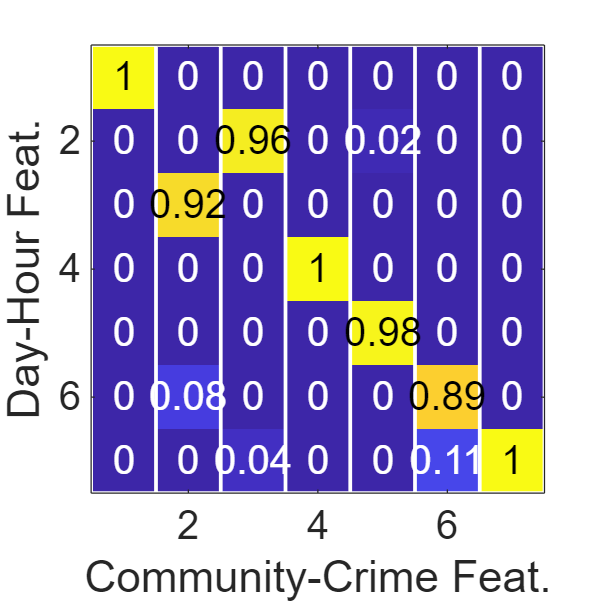

plot_mat(jr_idx(G_Y,[1,2]),'FontSize',16)
xlabel('Community-Crime Feat.');
ylabel('Day-Hour Feat.'); 
exportgraphics(gcf, 'jr_diagram12_34A.pdf', 'ContentType', 'vector')

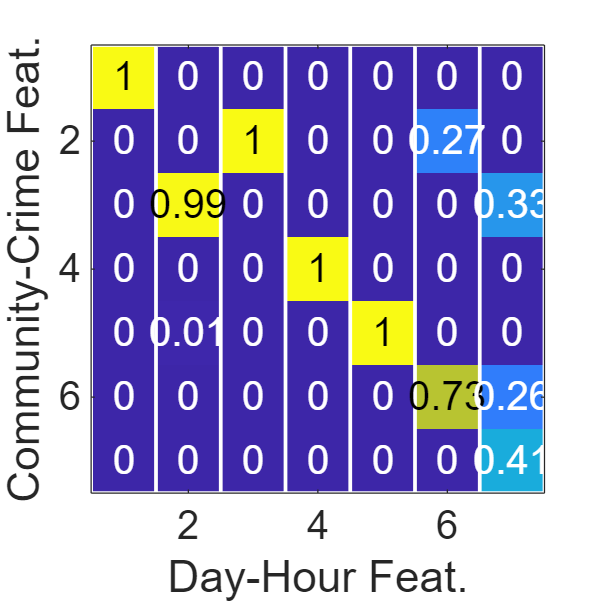


plot_mat(jr_idx(G_Y,[2,1]),'FontSize',16)
xlabel('Day-Hour Feat.'); 
ylabel('Community-Crime Feat.');
exportgraphics(gcf, 'jr_diagram12_34B.pdf', 'ContentType', 'vector')

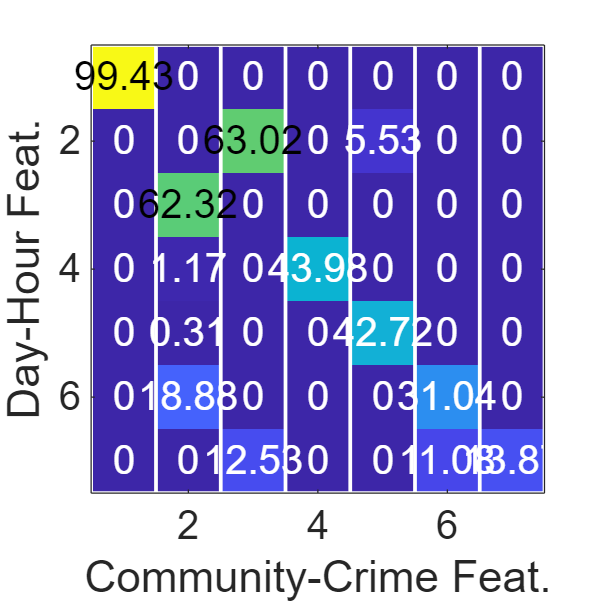


plot_mat(G_Y,'FontSize',16,'threshold',50)
clim([0,100]);
xlabel('Community-Crime Feat.');
ylabel('Day-Hour Feat.'); 
exportgraphics(gcf, 'jr_diagram12_34C.pdf', 'ContentType', 'vector')